# Problem 6.7

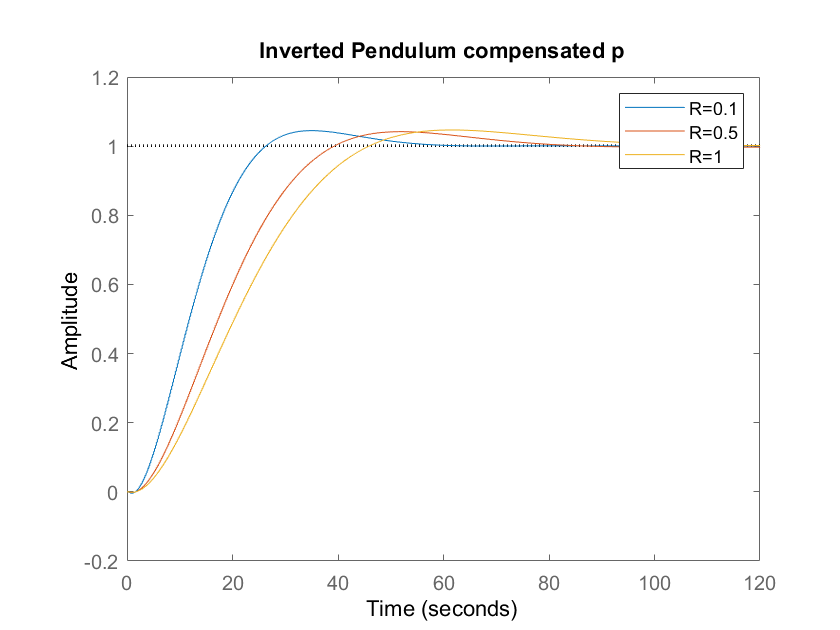


close all;
A_ip = [0 0 1 0; 0 0 0 1; 0 11.5 -1.84e-3 -8.08e-5; 0 7.2 -8.16e-4 -9.18e-5];
B_ip = [0 0 .0184 .00816]';
C_ip = [1 0 0 0; 0 1 0 0]; % First is p second is theta
D_ip = [0 0]';
h = 0.18;
sysc = ss(A_ip, B_ip, C_ip, D_ip);
sysd = c2d(sysc, h);
Q_ip = diag([1 1 0 0]);
K_a = lqr(sysd, Q_ip, 0.1); % R = 0.1
Kr_a = 1/-.52;
K_b = lqr(sysd, Q_ip, 0.5); % R = 0.5;
Kr_b = 1/-1.16;
K_c = lqr(sysd, Q_ip, 1); % R = 1;
Kr_c = 1/-1.63;
sysd_compa = ss(sysd.A - sysd.B*K_a, sysd.B*Kr_a, sysd.C, sysd.D, h);
sysd_compb = ss(sysd.A - sysd.B*K_b, sysd.B*Kr_b, sysd.C, sysd.D, h);
sysd_compc = ss(sysd.A - sysd.B*K_c, sysd.B*Kr_c, sysd.C, sysd.D, h);
sys_a = tf(sysd_compa);
sys_b = tf(sysd_compb);
sys_c = tf(sysd_compc);
figure;
hold on;
step(sys_a(1));
step(sys_b(1));
step(sys_c(1));
legend('R=0.1', 'R=0.5', 'R=1');
title('Inverted Pendulum compensated p');
hold off;

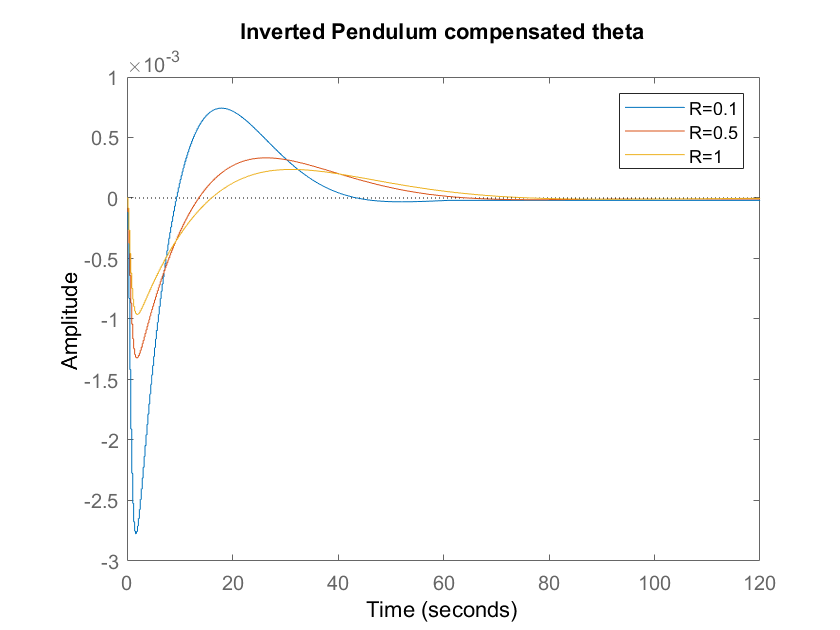

figure;
hold on;
step(sys_a(2));
step(sys_b(2));
step(sys_c(2));
legend('R=0.1', 'R=0.5', 'R=1');
title('Inverted Pendulum compensated theta');
hold off;

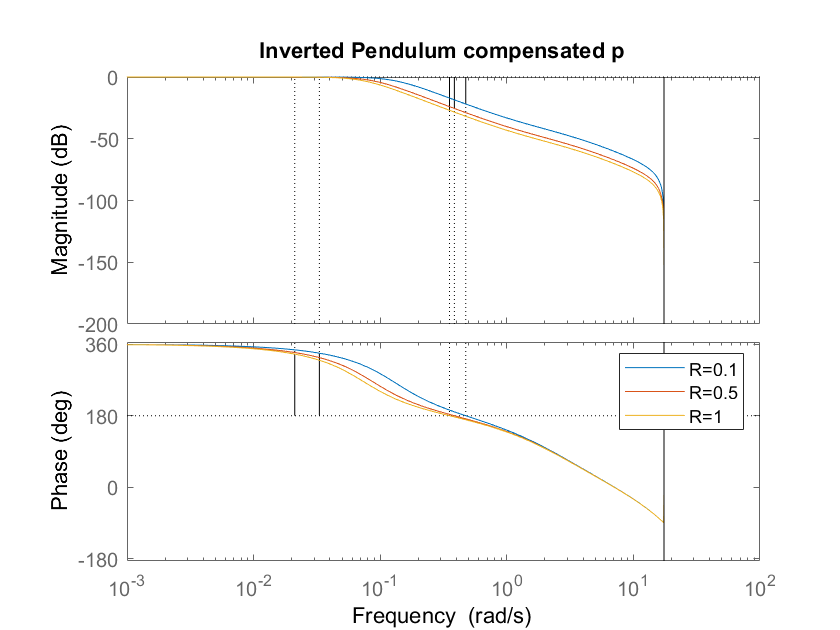

figure;
hold on;
margin(sys_a(1));
margin(sys_b(1));
margin(sys_c(1));
legend('R=0.1', 'R=0.5', 'R=1');
title('Inverted Pendulum compensated p');
hold off;

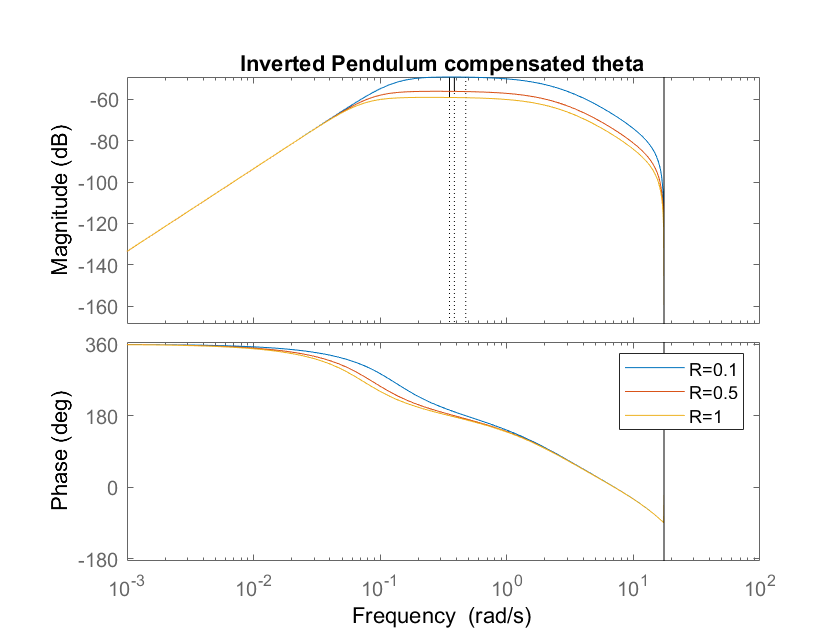

figure;
hold on;
margin(sys_a(2));
margin(sys_b(2));
margin(sys_c(2));
legend('R=0.1', 'R=0.5', 'R=1');
title('Inverted Pendulum compensated theta');
hold off;

Reducing R reduces settling time but increases overshoot and reduces phase margin.